# Example 1: Analysis of a TPMS unit cell

First, he fundamental properties of the structure need to be defined.

The first step is to set the structure **equation**, the most common TPMS-like functions can be accessed using their name. - 'Primitive', 'Diamond', 'Gyroid', 'Neovius', 'IWP', 'FRD'. Other example functions include 'Sphere', 'P-normCube' and 'Taurus'

Alternatively, a custom **equation** can be defined such as: *equation = @(x,y,z) cos(x).*sin(y)+cos(y).*sin(z)+cos(z).*sin(x)+(2*y-1);*

Next the **type** needs to be set - this sets how the equation is converted into a solid. 

'surface' creates a thickened surface, 'network' creates a more skeletal/strut like structure. 

'bounded' is reccomended for more advanced users, and utilises a lower and upper isovalue to create a more wide range of structures

Finally, **either** the target volume fraction **vf**, or the isovalue **v**, needs to be set. These two are alternatve methods of achieving the same result. volume fractions should be in the range of 0 to 1.

*As bounded requires two isovalues, and there is no direct formula for volume fraction - bounded uses v as the upper isovalue, and vf as the lower isovalues.

To create variable density/graded structures, either v or vf can be multiple inputs. Linear gradients should be input as an (Lx1) vector, 2D gradients should be an (LxM) matrix and 3D gradients should be (LxMxN) which will be remapped to stretch across bulk volume.

equation = ["Gyroid"]; %"Gyroid","Diamond","Primitive", "Neovius", "IWP", "FRD"
%equation = @(x,y,z) cos(x).*sin(y)+cos(y).*sin(z)+cos(z).*sin(x)+(2*y-1);
type = "network"; % Types: "network","surface","bounded"
vf = []; % Target Volume Fraction between 0 and 1 - (used for network and surface)
v = [0.25];% Isovalue(s) input as a scalar, vector, 2D or 3D array for network and surface (will be resampled uniformly). (2x1)

Next the resolution for the meshgrid, the size of the structure, number of unit cells, any rotations and/or offsets should be defined.

res = [25 25 25]; % Resolution - (number of voxels per edge in x,y,z)
sz = [10 10 10]; % Cell size - (size of the unit cell in x,y,z)
ncells = [2 2 2]; % Number of cells - (in x,y,z)
Reuler = [0 0 0]; % Euler Rotaions - (rotions in degrees pitch,roll,yaw)
offset = [0 0.25 0]; % Phase offset - (shift phase in x,y,z)

%TPMS(equation,type,v,vf,res,cellSize,ncells,Rxyz,offset)
myTPMS = TPMS(equation,type,v,vf,res,sz,ncells,Reuler,offset);

## Calculating the properties of the structure

To analyse a structure, the properties must be requested. This involves potentially generating a **v3field** object and/or a **trimesh** object, additionally a **metrics** object is created to simplify the outputs to scalar values which can be used to rapidly compare properties of different structures.

To request calculation of properties, the **myTPMS.properties**(field,mechanical,trimesh,curvaturemethod) method is used. The field, mechanical, trimesh and curvature method are all options which can turn on or off different calculation steps. If any input is not specified it will default to 1 - (which will calculate the proeprties).

As curvature can be calculated using different methods, a string should be input to select the method - 'patch', 'trimesh' or 'none'. (detailed explanations of this can be found in example 2.)

Turning on more requested properties will increase the computational time - particulaly at higher resolutions.

% MyStructure contains fields for the v3Field (F), trimesh (FV) and comparable metrics (M) 
% The various properties and substructres can be calculated using
% Turning on more inputs will increase the computational time
calculateFields = 1;  % 1 or 0 to turn on or off.
calculateMechanical = 1;  % 1 or 0 to turn on or off.
calculateTrimesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'none'; % 'patch', 'trimesh', 'none'

myTPMS = myTPMS.properties(calculateFields,calculateMechanical,calculateTrimesh,curvatureMethod);

% These various properties can be accessed and viewed using dot indexing or
% flattened to compare results using MyStructure.export
output = myTPMS.export;

## Plotting and visulisation

There are a range of different ways to plot/properties to visualse a generated structure. Show below are some of the common methods and properties that may be of interest

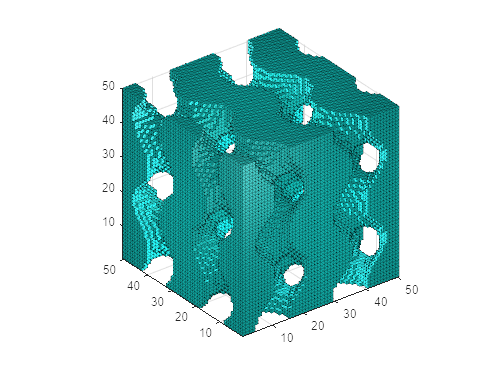

% The plot type may be defined using any of the following
% "trimesh"(default),"voxel","orthoslice","slice"...
%   ..."histogram","histogram2","polemap","tensor"
figure
h1 = myTPMS.plot([],"voxel");

## Any field can be visualised using orthosliceviewer

% property = "U ";
% figure;
%h2 =  myTPMS.plot(gca,"orthoslice",property);

## An XY slice may also be viewed at a defined percentage of the z-height

% property = "U"; 
% figure;
% h3 =  myTPMS.plot(gca,"slice",property);

## Different properties may be investigated by requesting them using a

string the space charecter is used as a delimiter, so the first word must match the property you wish to investigate

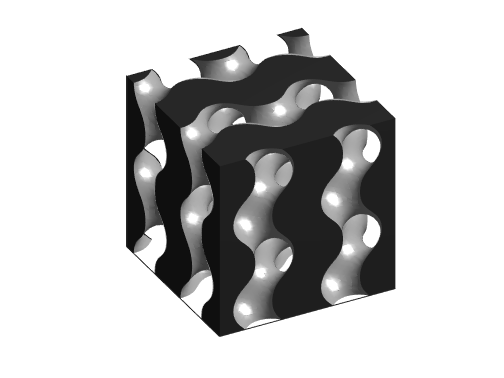

property = [];
figure;
opts.fancy = 1;
h4 =  myTPMS.plot(gca,"trimesh",property,[],opts);

## The histogram option requires shows the area-weighted distribution of a given property

properties may interact - the proeprties must have the same data size - (i.e per vertex data cannot be compared to per face data)

% property = "Ra";
% figure
% h0 = myTPMS.plot(gca,"histogram",property);

## The histogram2 option requires 2 options, and can show how 2 different

properties may interact - the proeprties must have the same data size - (i.e per vertex data cannot be compared to per face data)

% property = "inclination angle (deg)";
% property2 = "GC";
% figure
% h5 = myTPMS.plot(gca,"histogram2",property,property2,100);

## The polemap option creates an area-weighted pole map based on the surface normals

% figure
% h6 = myTPMS.plot(gca,"polemap");

## The tensor option plots a visualisation of the stiffness tensor.

this treats the entire structure as the periodic unit cell

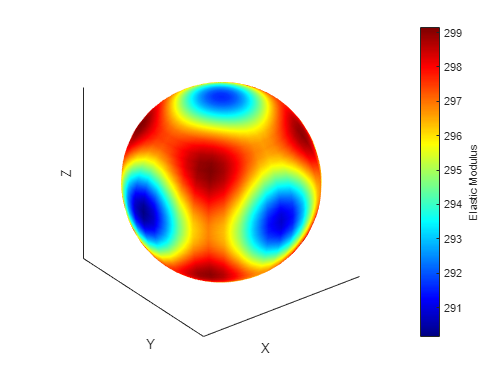

figure
h7 = myTPMS.plot(gca,"tensor");